# Lecture 12: Image Thresholding

# Part 1: Global Thresholding

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in the images folder of the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture12 - Image Thresholding

- pdf versions of the .mlx files are also available for those using GNU Octave

clearvars; close all; clc;

## Basic Global Thresholding vs. Optimum Global (Otsu) Thresholding

- You can use the images in images folder. (fingerprint, rice, coins, otsu)

- Compare the values of T, T2, and EM.

- Basic global thresholding may produce different results, at each run.

- To see the effect of noise, compare the results of noise1 and noise2 images. (noise2 is the smoothed version of noise1)

- Check the documentations of *imbinarize*, *graythresh*, *otsuthresh* functions

% read input image
I = imread('images/fingerprint.png');
if(size(I,3) == 3) % convert to grayscale if needed
    I=rgb2gray(I); 
end

% input image and its histogram
subplot(2,2,1), imshow(I), title('Original Image');
subplot(2,2,2), imhist(I), axis square, title('Histogram');

**Basic Global Thresholding**

T = gbt(I(:)); % call gbt function (It is not a built-in IPT function, see gbt.m and licence.txt)
title_str = strcat('Basic Global Thresholding (T = ', num2str(round(T)), ')');
subplot(2,2,3), imshow(imbinarize(I,T/255)), title(title_str); % plot thresholded image

**Optimum Global Thresholding: Otsu's method**

You can directly use *BW = imbinarize(I)*. BW will be the binary image thresholded with Otsu method. 

But to obtain the threshold level and effectivenes metric, use *graythresh* or *otsuthresh*.

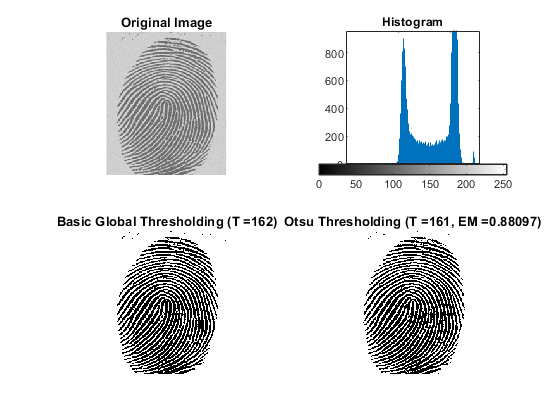

[T2, EM] = graythresh(I); 
%[T2, EM] = otsuthresh(imhist(I)); % also check otsuthresh()
kstar = round(T2*255); % optimum threshold value
title_str = strcat('Otsu Thresholding (T = ', num2str(kstar), ', EM = ', num2str(EM), ')');
subplot(2,2,4), imshow(imbinarize(I,T2)), title(title_str);